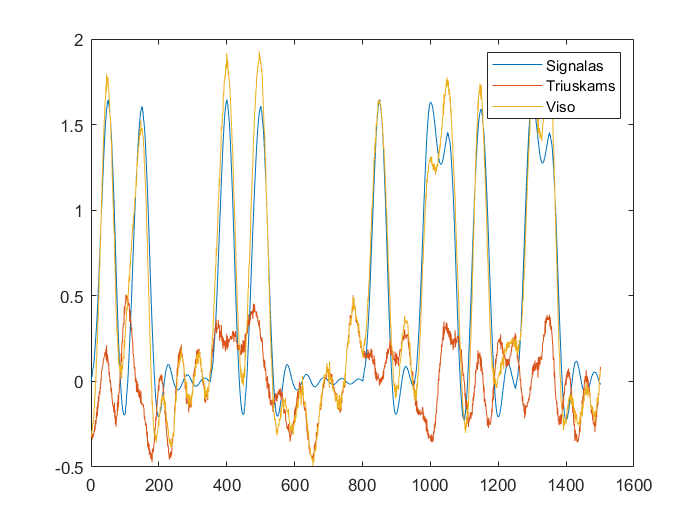

idealSignal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


noisySignal =     0.0029   -0.0302   -0.0145   -0.0126   -0.0687   -0.0156   -0.0393   -0.0534   -0.0137   -0.0490   -0.0450   -0.0343   -0.0732   -0.0325   -0.0903   -0.0051   -0.0735   -0.0419   -0.0471   -0.0847   -0.0162   -0.0755   -0.0498   -0.0132   -0.0792   -0.0260   -0.0521   -0.0466   -0.0503    0.0068   -0.0345   -0.0002   -0.0022   -0.0354    0.0078   -0.0187   -0.0043    0.0063   -0.0137    0.0334   -0.0133    0.0289   -0.0039    0.0348    0.0538    0.0065    0.0183    0.0607   -0.0032    0.0336


discretizedSignal =     0.0029   -0.0450   -0.0162   -0.0345   -0.0133    0.0387    0.0233   -0.1147   -0.0964   -0.0779    0.0734    0.2344    0.2453    0.1851    0.0912   -0.0563   -0.0921   -0.0830    0.0730    0.1604    0.0878   -0.1023   -0.2608   -0.2749   -0.0438    0.1902    0.3329    0.1540   -0.0172   -0.1499   -0.2211   -0.2702   -0.3584   -0.4202   -0.3348   -0.0878    0.1147    0.1146    0.0250   -0.1457   -0.2526   -0.2319   -0.2057   -0.1653   -0.0271    0.0658    0.2206    0.4022    0.4089    0.3892


ADCsignal =      1     0     0     0     0     7     4     0     0     0    13    43    45    34    17     0     0     0    13    29    16     0     0     0     0    35    61    28     0     0     0     0     0     0     0     0    21    21     5     0     0     0     0     0     0    12    40    73    74    71


ADCpreambule =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255


signalSNR_db = 11.2119

%https://www.gaussianwaves.com/2019/11/shannons-limit-on-power-efficiency/
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule, signalSNR_db] = GenerateSignal(dataSend, generuojama_amplitude)

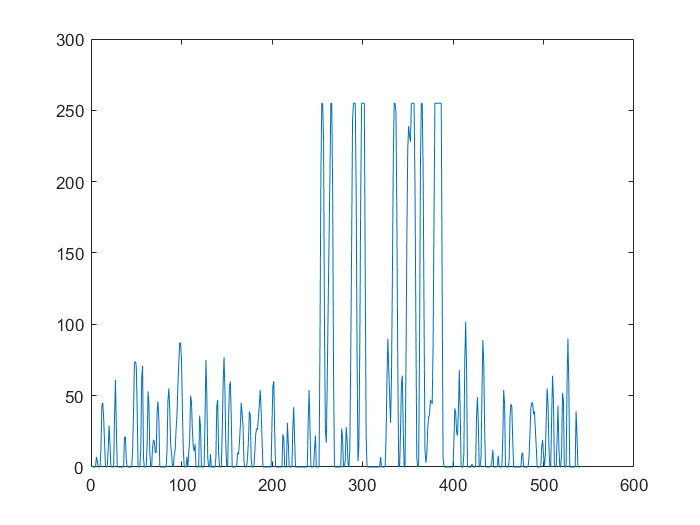

plot(ADCsignal)

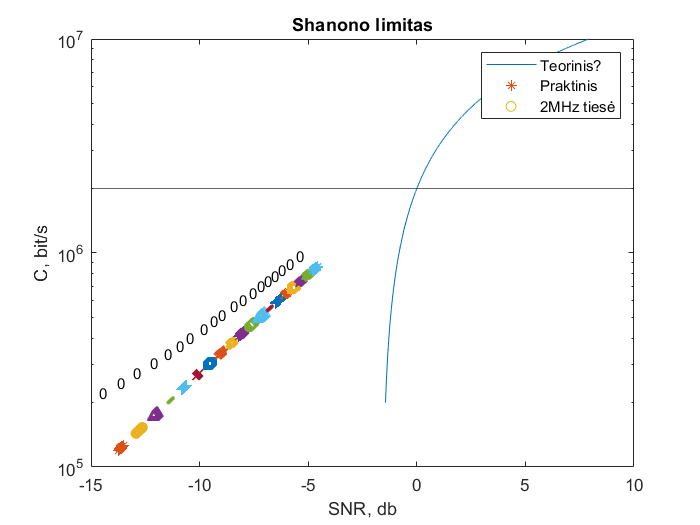


B = 2E6;
%{
for i = 0.5:0.1:1.4
    [idealSignal3, noisySignal3, discretizedSignal3, ADCsignal3, ADCpreambule3, signalSNR_db] = GenerateSignal(dataSend, i);
    ADCsignal2 = [ADCsignal2, ADCsignal3];

    sugeneruoti_triuksmai_db = [sugeneruoti_triuksmai_db, signalSNR_db];
    shanono_bit_capacity = [shanono_bit_capacity, log2(1+db2pow(signalSNR_db))];
end
%}

%Teorines
teor_sugeneruoti_triuksmai_db = [];
teor_shanono_bit_capacity = [];
for i = 0.1:0.001:5
    signalSNR_db = pow2db(i);
    teor_sugeneruoti_triuksmai_db = [teor_sugeneruoti_triuksmai_db, pow2db((2^db2pow(signalSNR_db)-1)/db2pow(signalSNR_db))];
    teor_shanono_bit_capacity = [teor_shanono_bit_capacity, i]; %log2(1+db2mag(signalSNR_db))]%[teor_shanono_bit_capacity, (2^db2pow(signalSNR_db)-1)/db2pow(signalSNR_db)]; %log2(1+db2mag(signalSNR_db))];
end

%Praktines
shanono_bit_capacity = [];
sugeneruoti_triuksmai_db = [];

sugeneruoti_triuksmai_db = kiekvienas_snr_db;
shanono_bit_capacity = B*log2(1+db2pow(kiekvienas_snr_db));
fmt = ['*','o','^','.','+','x','s','p','h', '*','o','^','.','+','x','s','p','h', '*','o','^','.','+','x','s','p','h'];

figure
semilogy(teor_sugeneruoti_triuksmai_db, teor_shanono_bit_capacity*B)
hold on
for i = 1:size(shanono_bit_capacity, 1)
    scatter(sugeneruoti_triuksmai_db(i, :), shanono_bit_capacity(i, :), fmt(i))
    text(sugeneruoti_triuksmai_db(i, 1)-1, shanono_bit_capacity(i, 1)+100000, string(viso_neteisingi_d(i)), 'FontSize',9)
end

yline(2e6)
title("Shanono limitas")
xlabel("SNR, db")
ylabel("C, bit/s")
legend("Teorinis?", "Praktinis", "2MHz tiesė")
hold off